%data = readtable('C:\class\coursefiles\mlbe\electricity\electricity.xlsx',...
%                 'Delimiter','comma','Sheet',1,'Range','B2:B13')

data = readtable('C:\class\coursefiles\mlbe\electricity\electricity.xlsx')

data =       Date       Residential    Commercial    Industrial      Total   
    _________    ___________    __________    __________    __________

    1/1/1990      9.542e+07     6.2499e+07    7.5188e+07    2.4087e+08
    2/1/1990     7.4498e+07     5.6912e+07    7.4607e+07    2.1336e+08
    3/1/1990     7.1902e+07      5.798e+07    7.6842e+07    2.1407e+08
    4/1/1990     6.5191e+07     5.6481e+07    7.6238e+07    2.0507e+08
    5/1/1990     6.2881e+07     5.8941e+07    7.8759e+07    2.0815e+08
    6/1/1990       7.39e+07     6.4609e+07    8.0676e+07    2.2704e+08
    7/1/1990     9.0935e+07     7.0948e+07    8.1116e+07    2.5159e+08
    8/1/1990     8.8564e+07     7.1119e+07    8.4045e+07    2.5211e+08
    9/1/1990      8.624e+07     6.9296e+07    8.1611e+07    2.4518e+08
    10/1/1990    6.9595e+07     6.3098e+0


[num,txt] = xlsread('C:\class\coursefiles\mlbe\electricity\electricity.xlsx');    % num is a matrix, txt is a cell array

data{:,2:5};
sectors = data.Properties.VariableNames(2:end)

sectors =     'Residential'    'Commercial'    'Industrial'    'Total'



usage = data{:,sectors}

usage =     95420231    62498967    75187693   240874655
    74498370    56912068    74606540   213362594
    71901767    57979978    76841977   214067173
    65190618    56480718    76238153   205071739
    62881008    58940835    78758806   208151658
    73899811    64609125    80676340   227042513
    90935492    70948145    81116187   251589853
    88563829    71119498    84045130   252113432
    86239965    69295956    81611206   245181443
    69595203    63098049    81959284   222306541


dates = data.Date

dates =    1/1/1990 
   2/1/1990 
   3/1/1990 
   4/1/1990 
   5/1/1990 
   6/1/1990 
   7/1/1990 
   8/1/1990 
   9/1/1990 
   10/1/1990
   11/1/1990
   12/1/1990
   1/1/1991 
   2/1/1991 
   3/1/1991 
   4/1/1991 
   5/1/1991 
   6/1/1991 
   7/1/1991 
   8/1/1991 
   9/1/1991 
   10/1/1991
   11/1/1991
   12/1/1991
   1/1/1992 
   2/1/1992 
   3/1/1992 
   4/1/1992 
   5/1/1992 
   6/1/1992 
   7/1/1992 
   8/1/1992 
   9/1/1992 
   10/1/1992
   11/1/1992
   12/1/1992
   1/1/1993 
   2/1/1993 
   3/1/1993 
   4/1/1993 
   5/1/1993 
   6/1/1993 
   7/1/1993 
   8/1/1993 
   9/1/1993 
   10/1/1993
   11/1/1993
   12/1/1993
   1/1/1994 
   2/1/1994 
   3/1/1994 
   4/1/1994 
   5/1/1994 
   6/1/1994 
   7/1/1994 
   8/1/1994 
   9/1/1994 
   10/1/1994
   11/1/1994
   12/1/1994
   1/1/1995 
   2/1/1995 
   3/1/1995 
   4/1/1995 
   5/1/1995 
   6/1/1995 
   7/1/1995 
   8/1/1995 
   9/1/1995 
   10/1/1995
   11/1/1995
   12/1/1995
   1/1/1996 
   2/1/1996 
   3/1/1996 
   4/1/1996 
   5

residental = data.Residential

residental =     95420231
    74498370
    71901767
    65190618
    62881008
    73899811
    90935492
    88563829
    86239965
    69595203


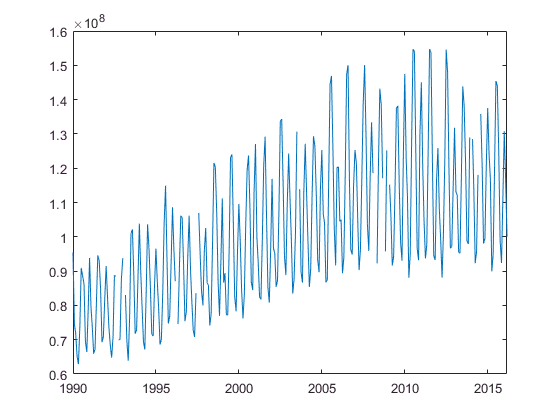


plot(dates,residental)

## Make time a uniform variable from months

dates(end)

ans =    3/1/2016


calmonths(1)

ans =    1mo


nextmonth = dates(end) + calmonths(1)

nextmonth =    4/1/2016



datesplus1 = [dates;nextmonth] % concatinate next month to dates

datesplus1 =    1/1/1990 
   2/1/1990 
   3/1/1990 
   4/1/1990 
   5/1/1990 
   6/1/1990 
   7/1/1990 
   8/1/1990 
   9/1/1990 
   10/1/1990
   11/1/1990
   12/1/1990
   1/1/1991 
   2/1/1991 
   3/1/1991 
   4/1/1991 
   5/1/1991 
   6/1/1991 
   7/1/1991 
   8/1/1991 
   9/1/1991 
   10/1/1991
   11/1/1991
   12/1/1991
   1/1/1992 
   2/1/1992 
   3/1/1992 
   4/1/1992 
   5/1/1992 
   6/1/1992 
   7/1/1992 
   8/1/1992 
   9/1/1992 
   10/1/1992
   11/1/1992
   12/1/1992
   1/1/1993 
   2/1/1993 
   3/1/1993 
   4/1/1993 
   5/1/1993 
   6/1/1993 
   7/1/1993 
   8/1/1993 
   9/1/1993 
   10/1/1993
   11/1/1993
   12/1/1993
   1/1/1994 
   2/1/1994 
   3/1/1994 
   4/1/1994 
   5/1/1994 
   6/1/1994 
   7/1/1994 
   8/1/1994 
   9/1/1994 
   10/1/1994
   11/1/1994
   12/1/1994
   1/1/1995 
   2/1/1995 
   3/1/1995 
   4/1/1995 
   5/1/1995 
   6/1/1995 
   7/1/1995 
   8/1/1995 
   9/1/1995 
   10/1/1995
   11/1/1995
   12/1/1995
   1/1/1996 
   2/1/1996 
   3/1/1996 
   4/1/1996 

dur = diff(datesplus1)

dur =    744:00:00
   672:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   672:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   696:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   672:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   672:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   672:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   720:00:00
   744:00:00
   720:00:00
   744:00:00
   744:00:00
   696:00:00
   744:00:00
   720:00:00
   744


daysPerMonth = days(dur)

daysPerMonth =     31
    28
    31
    30
    31
    30
    31
    31
    30
    31



NormResidental = residental./daysPerMonth

NormResidental =    1.0e+06 *

    3.0781
    2.6607
    2.3194
    2.1730
    2.0284
    2.4633
    2.9334
    2.8569
    2.8747
    2.2450


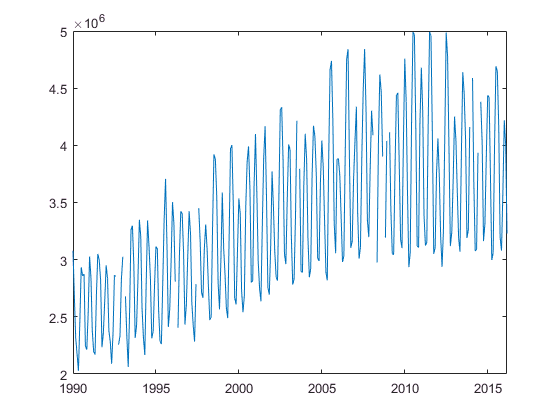

plot(dates,NormResidental)

usage = usage./daysPerMonth

usage =    1.0e+06 *

    3.0781    2.0161    2.4254    7.7702
    2.6607    2.0326    2.6645    7.6201
    2.3194    1.8703    2.4788    6.9054
    2.1730    1.8827    2.5413    6.8357
    2.0284    1.9013    2.5406    6.7146
    2.4633    2.1536    2.6892    7.5681
    2.9334    2.2886    2.6167    8.1158
    2.8569    2.2942    2.7111    8.1327
    2.8747    2.3099    2.7204    8.1727
    2.2450    2.0354    2.6438    7.1712


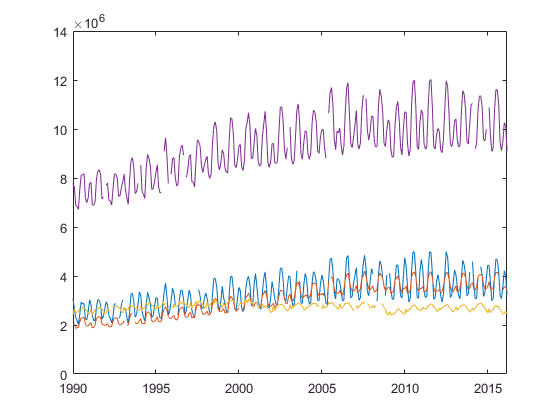

plot(dates,usage)

% subtract mean, divide by standard deviation. Makes unitless
zusage = zscore(usage)

zusage =    NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN
   NaN   NaN   NaN   NaN



idx = ~any(isnan(usage),2)    % 2 means

idx =    1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   1
   1
   1
   0
   0
   1
   1
   1
   1
   1
   0
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   0
   0
   1
   1
   1
   0
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   0
   0
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


zusage = zscore(usage(idx,:))    % revmoced missing data to normalize

zusage =    -0.3865   -1.5816   -2.2347   -1.2206
   -0.9929   -1.5561   -0.5146   -1.3429
   -1.4887   -1.8072   -1.8508   -1.9256
   -1.7014   -1.7880   -1.4012   -1.9824
   -1.9115   -1.7592   -1.4060   -2.0812
   -1.2796   -1.3688   -0.3370   -1.3853
   -0.5967   -1.1598   -0.8589   -0.9388
   -0.7078   -1.1513   -0.1793   -0.9251
   -0.6820   -1.1270   -0.1128   -0.8924
   -1.5968   -1.5517   -0.6633   -1.7089



ridx = isnan(usage(:,1))

ridx =    0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   

mean(usage,'omitnan')

ans =    1.0e+06 *

    3.3473    3.0386    2.7352    9.2823


nnz(isnan(usage))

ans = 37

sum(isnan(usage))

ans =     11     6    10    10


idx = ismissing(data)    % for table

idx =    0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   1
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   1   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   1   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   1   0   0   0
   0   0   1   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   0   1   0   0
   0   0   0   0   0
   0   0   0   0   0
   0   

idx = ~any(ismissing(data)) % rows that are not missing data

idx =    1   0   0   0   0


x = [1 2 3 nan 4 nan 7]

x =      1     2     3   NaN     4   NaN     7


[y,idx] = rmmissing(x)

y =      1     2     3     4     7


idx =    0   0   0   1   0   1   0



resUsage = usage(:,1);
resUsageOK = rmmissing(resUsage)

resUsageOK =    1.0e+06 *

    3.0781
    2.6607
    2.3194
    2.1730
    2.0284
    2.4633
    2.9334
    2.8569
    2.8747
    2.2450



idxOK = ~ismissing(resUsage)

idxOK =    1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
  

datesOK = dates(idxOK)

datesOK =    1/1/1990 
   2/1/1990 
   3/1/1990 
   4/1/1990 
   5/1/1990 
   6/1/1990 
   7/1/1990 
   8/1/1990 
   9/1/1990 
   10/1/1990
   11/1/1990
   12/1/1990
   1/1/1991 
   2/1/1991 
   3/1/1991 
   4/1/1991 
   5/1/1991 
   6/1/1991 
   7/1/1991 
   8/1/1991 
   9/1/1991 
   10/1/1991
   11/1/1991
   12/1/1991
   1/1/1992 
   2/1/1992 
   3/1/1992 
   4/1/1992 
   5/1/1992 
   6/1/1992 
   7/1/1992 
   8/1/1992 
   10/1/1992
   11/1/1992
   12/1/1992
   1/1/1993 
   3/1/1993 
   4/1/1993 
   5/1/1993 
   6/1/1993 
   7/1/1993 
   8/1/1993 
   9/1/1993 
   10/1/1993
   11/1/1993
   12/1/1993
   1/1/1994 
   2/1/1994 
   3/1/1994 
   4/1/1994 
   5/1/1994 
   6/1/1994 
   7/1/1994 
   8/1/1994 
   9/1/1994 
   10/1/1994
   11/1/1994
   12/1/1994
   1/1/1995 
   2/1/1995 
   3/1/1995 
   4/1/1995 
   5/1/1995 
   6/1/1995 
   7/1/1995 
   8/1/1995 
   9/1/1995 
   10/1/1995
   11/1/1995
   12/1/1995
   1/1/1996 
   2/1/1996 
   3/1/1996 
   5/1/1996 
   6/1/1996 
   7/1/1996 
  

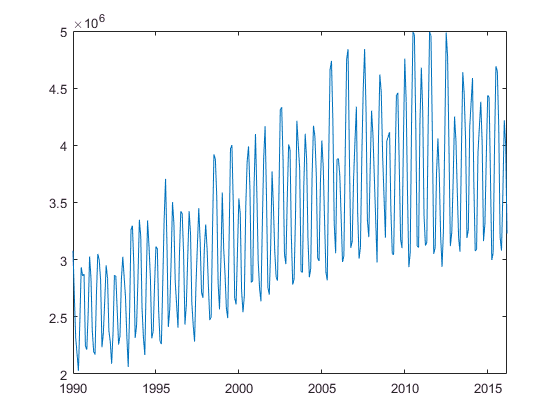


plot(datesOK, resUsageOK)

dataOK = rmmissing(data)

dataOK =       Date       Residential    Commercial    Industrial      Total   
    _________    ___________    __________    __________    __________

    1/1/1990      9.542e+07     6.2499e+07    7.5188e+07    2.4087e+08
    2/1/1990     7.4498e+07     5.6912e+07    7.4607e+07    2.1336e+08
    3/1/1990     7.1902e+07      5.798e+07    7.6842e+07    2.1407e+08
    4/1/1990     6.5191e+07     5.6481e+07    7.6238e+07    2.0507e+08
    5/1/1990     6.2881e+07     5.8941e+07    7.8759e+07    2.0815e+08
    6/1/1990       7.39e+07     6.4609e+07    8.0676e+07    2.2704e+08
    7/1/1990     9.0935e+07     7.0948e+07    8.1116e+07    2.5159e+08
    8/1/1990     8.8564e+07     7.1119e+07    8.4045e+07    2.5211e+08
    9/1/1990      8.624e+07     6.9296e+07    8.1611e+07    2.4518e+08
    10/1/1990    6.9595e+07     6.3098e

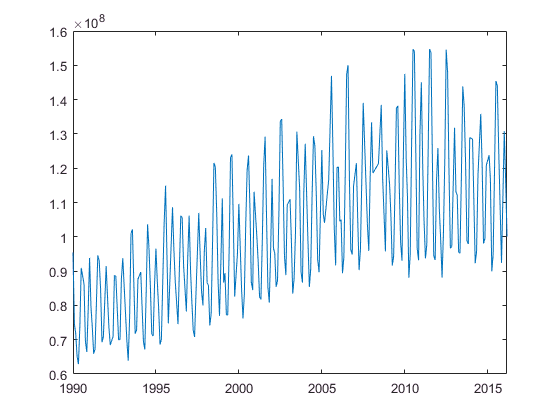

plot(dataOK.Date,dataOK.Residential)

resUsage(~idxOK) = [];    % dangerous method for deleting

resUsage = usage(:,1);

plot(dates,resUsage,'b-')

% interpolation
eqfill = fillmissing(resUsage,'linear')

eqfill =    1.0e+06 *

    3.0781
    2.6607
    2.3194
    2.1730
    2.0284
    2.4633
    2.9334
    2.8569
    2.8747
    2.2450


linfill = fillmissing(resUsage,'spline',...
            'SamplePoints',dates)

linfill =    1.0e+06 *

    3.0781
    2.6607
    2.3194
    2.1730
    2.0284
    2.4633
    2.9334
    2.8569
    2.8747
    2.2450


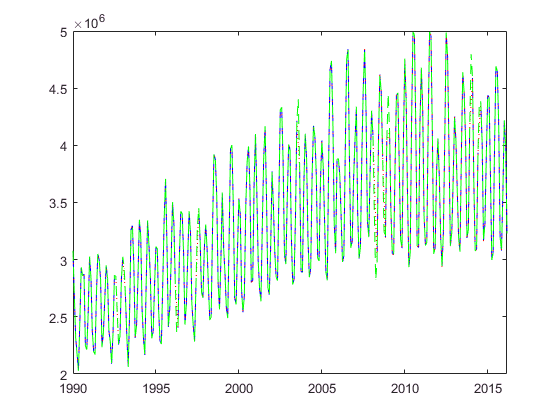

hold on
plot(dates,eqfill,'r:')
plot(dates,linfill,'g--')
hold off

corrcoef(usage(:,1:3),'rows','complete')    % only rows without nans

ans =     1.0000    0.8237    0.1390
    0.8237    1.0000    0.1620
    0.1390    0.1620    1.0000


corrcoef(usage(:,1:3),'rows','pairwise')    % only rows without nans

ans =     1.0000    0.8242    0.1462
    0.8242    1.0000    0.1535
    0.1462    0.1535    1.0000


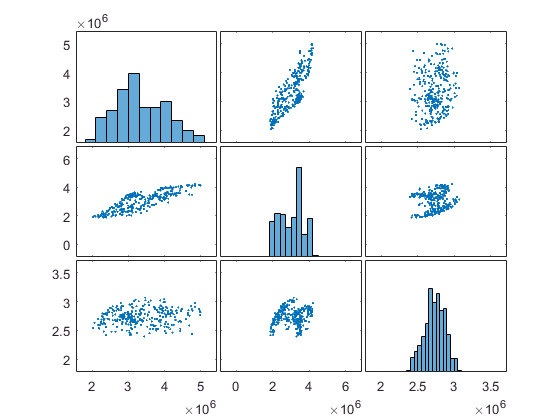


plotmatrix(usage(:,1:3))

% s = movmean(x,3) % moving average
usageF = fillmissing(usage,'spline','SamplePoints',dates)

usageF =    1.0e+06 *

    3.0781    2.0161    2.4254    7.7702
    2.6607    2.0326    2.6645    7.6201
    2.3194    1.8703    2.4788    6.9054
    2.1730    1.8827    2.5413    6.8357
    2.0284    1.9013    2.5406    6.7146
    2.4633    2.1536    2.6892    7.5681
    2.9334    2.2886    2.6167    8.1158
    2.8569    2.2942    2.7111    8.1327
    2.8747    2.3099    2.7204    8.1727
    2.2450    2.0354    2.6438    7.1712


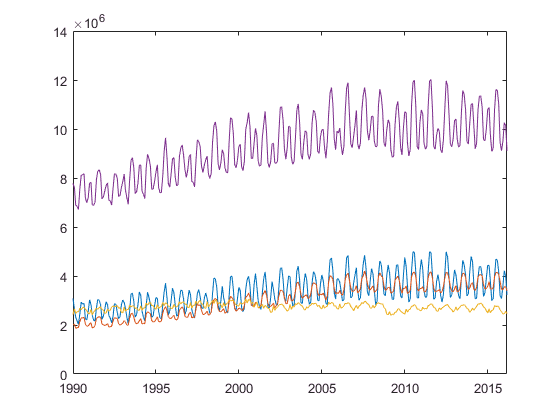


plot(dates,usageF)


ResUsage = usageF(:,1)

ResUsage =    1.0e+06 *

    3.0781
    2.6607
    2.3194
    2.1730
    2.0284
    2.4633
    2.9334
    2.8569
    2.8747
    2.2450


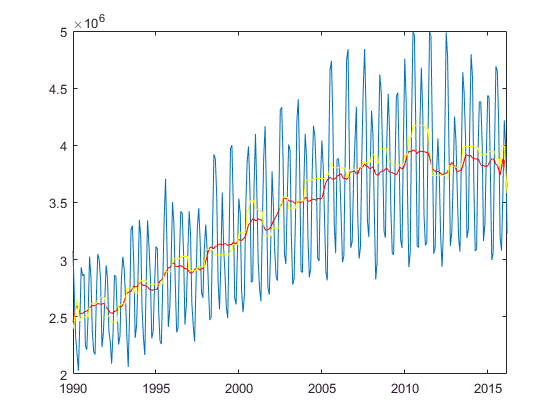

plot(dates,ResUsage)

usageMovAvg = movmean(ResUsage, 12);
usageMovMed = movmedian(ResUsage, 12);
hold on
plot(dates, usageMovAvg, 'r-')
plot(dates,usageMovMed,'y-')
hold off


usageStdAvg = movstd(ResUsage, 12)

usageStdAvg =    1.0e+05 *

    3.7695
    3.8893
    3.7901
    3.6933
    3.6573
    3.6256
    3.4569
    3.3867
    3.4868
    3.4547


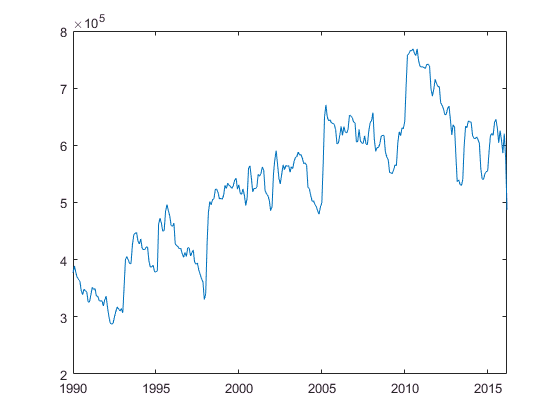

plot(dates, usageStdAvg)

n = 100;

elapsedYears = years(dates - dates(1));
c = polyfit(elapsedYears,ResUsage,1)    % polynomial of degree 1

c =    1.0e+06 *

    0.0593    2.5770


c(1)    % extract slope

ans = 5.9326e+04

y = polyval(c, elapsedYears);

future = polyval(c,elapsedYears(end)+10)

future = 4.7224e+06

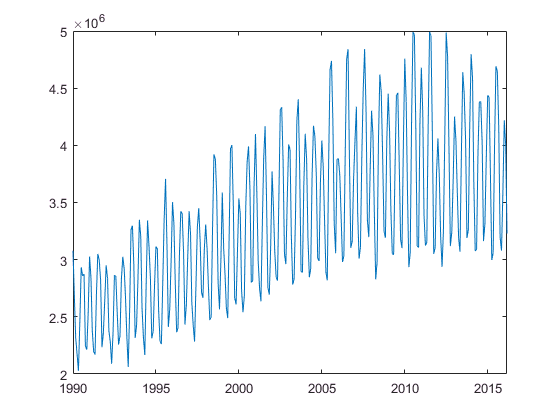


plot(dates, ResUsage)
hold on

plot(dates(n:end),y,'color',[1 0.5 0],'Linewidth',2)

Error using plot
Vectors must be the same length.

plot(dates(100),ResUsage(100),'ro')
ourlabel = ['Begin Prediction ',num2str(ResUsage(100)),'for Residential', 163]
text(dates(100),ResUsage(100)-1e6, ourlabel)
hold off


xlabel('time')
ylabel('usage')
title('residental usage \gamma')
legend('data','fit','Location','NW')


